% This live script exists to make plots
% Real data mean error
algorithmNames = {'DESC-geodesic', 'DESC-GCW', 'IRLS-GM', 'IRLS-L12',...
    'CEMP-MST', 'CEMP-GCW', 'MPLS'}; % Not reporting DESC MST
datasets = categorical({'Montreal Notre Dame', 'Notre Dame', 'NYC Library',...
    'Ellis Island', 'Madrid Metropolis',...
    'Piazza del Popolo', 'Roman Forum', 'Piccadilly',... 
    'Tower of London', 'Union Square', 'Vienna Cathedral',...
    'Yorkminster', 'Alamo'}); % 'Gendarmenmarkt' removed after Ellis Island

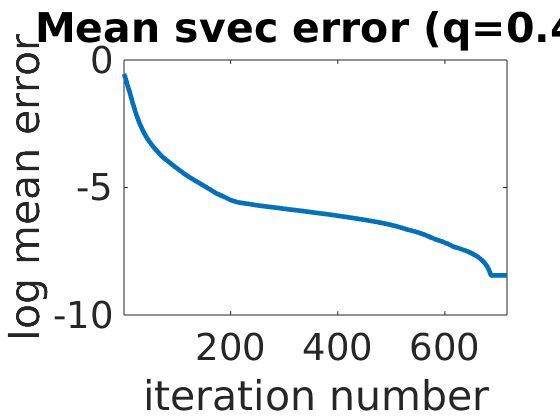

% Linear convergence
% MSE_means = csvread("linear_convergence_svec_error.csv");
% plot(log10(MSE_means), 'LineWidth', 3.5);
% xlim([1 inf]);
% title('Mean svec error (q=0.4)');
% xlabel('iteration number');
% ylabel('log mean error');
% ax = gca;
% ax.FontSize = 28;

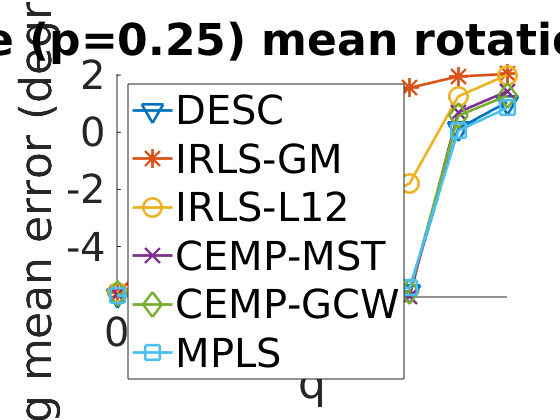

noiseLevel = 'Sparse (p=0.25) mean rotation errors'


% Sparse graph for rebuttal 
% Synthetic data mean error 
% q = 0:0.1:0.8;
% qvals = length(q);
% sigma = [0 0.1 0.5 1];
% marker = ["-v", "-*", "-o", "-x", "-d", "-s"];
% markerSize = 14; 
% synthetic_errors = csvread('raw_means_sparse_025_200.csv');
% clf;
% tiledlayout(1,1);
% for i = 1 % only using sigma 0 and 0.1
%     %subplot(1,1, i)
%     nexttile;
%     hold on;
%     xlim([0 0.8])
%     valrange = (1 + qvals*(i-1)):(qvals*i);
%     data = synthetic_errors(valrange, :);
%     for j = 1:length(algorithmNames)
%         plot(q,log10(data(:, j)), marker(j), 'DisplayName', algorithmNames{j},...
%             'LineWidth', 2, 'MarkerSize', markerSize);
%     end
%     xlabel('q')
%     ylabel('log mean error (degrees)')
%     noiseLevel = sprintf('Sparse (p=0.25) mean rotation errors')%, \\sigma = %0.2f', sigma(i));
%     title(noiseLevel);
%     ax = gca;
%     ax.FontSize = 30;
%     legend('Location', 'northwest', 'FontSize', 30);
%     hold off;
% end

% 


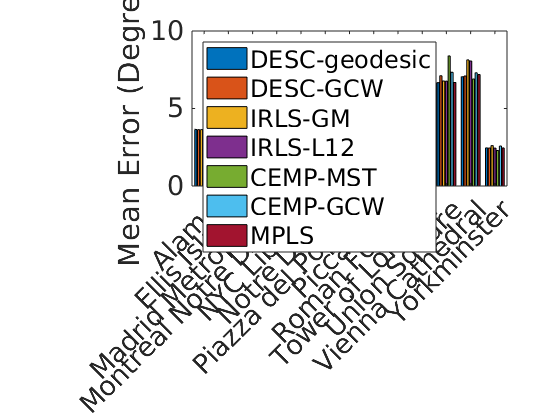


errors = csvread("real_data_raw_results_geodesic.csv");
%csvread("real_data_raw_no_gendarmenmarkt.csv");
h = bar(datasets, errors);

%set(h, {'DisplayName'}, algorithmNames);
ylabel('Mean Error (Degrees)')
legend(algorithmNames, 'Location', 'northwest');
ax = gca;
ax.FontSize = 20;


mean_over_datasets = mean(errors, 1)

mean_over_datasets =     3.5119    3.8354    3.9644    3.8447    4.1447    3.9191    3.7142


median_over_datasets = median(errors, 1)

median_over_datasets =     3.2187    3.2145    3.4197    3.4118    3.2662    3.5072    3.2050


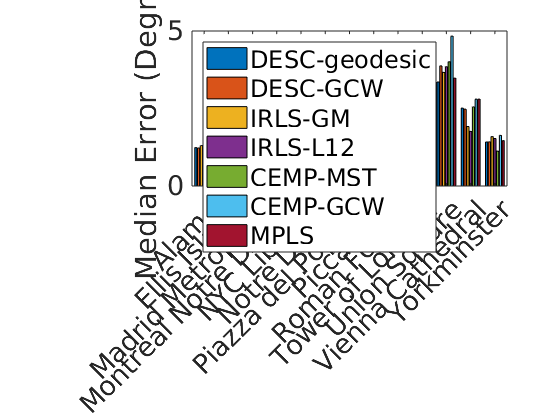

errors = csvread("raw_real_data_medians_geodesic.csv");
%csvread("raw_real_data_median_errors.csv");
h = bar(datasets, errors);

%set(h, {'DisplayName'}, algorithmNames);
ylabel('Median Error (Degrees)')
legend(algorithmNames, 'Location', 'northwest');
ax = gca;
ax.FontSize = 20;


mean_over_datasets = mean(errors, 1)

mean_over_datasets =     1.5938    1.8516    1.7255    1.7201    1.7975    2.0339    1.7032


median_over_datasets = median(errors, 1)

median_over_datasets =     1.4176    1.4253    1.5940    1.5743    1.5924    1.6321    1.4630


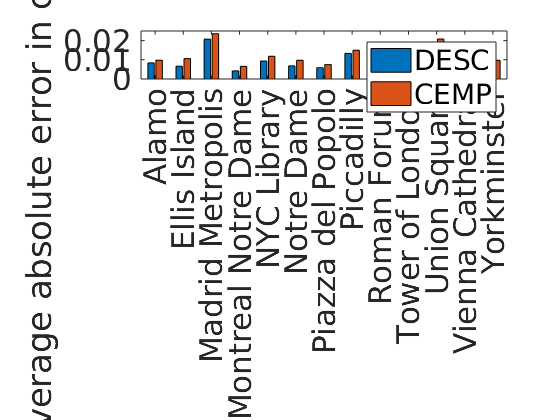

svec_errs = csvread("svec_desc_vs_cemp_means_geodesic.csv"); 
%csvread('svec_desc_vs_cemp.csv');
bar(datasets, svec_errs);
ylabel('Average absolute error in corruption estimates');
legend({'DESC' 'CEMP'})
ax = gca;
ax.FontSize = 23;

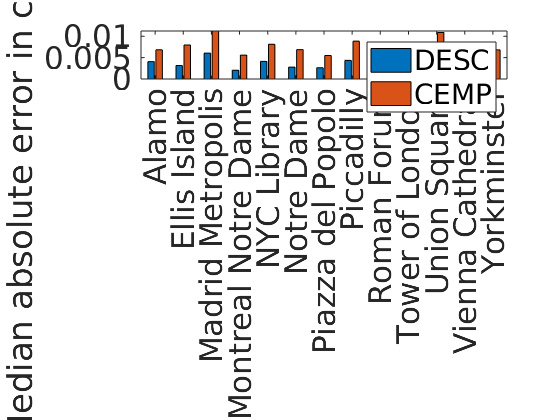

svec_median_errs = csvread("svec_desc_vs_cemp_medians_geodesic.csv");
%csvread('svec_desc_vs_cemp_medians.csv');
bar(datasets, svec_median_errs);
ylabel('Median absolute error in corruption estimates');
legend({'DESC' 'CEMP'})
ax = gca;
ax.FontSize = 23;

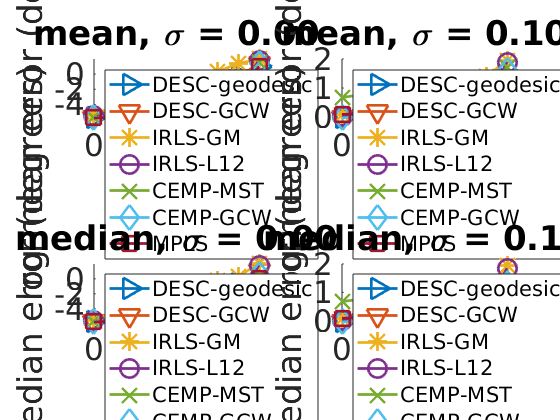

% Synthetic data mean error 
q = 0:0.1:0.8;
qvals = length(q);
sigma = [0 0.1 0.5 1];
marker = ["->","-v", "-*", "-o", "-x", "-d", "-s"];
markerSize = 14; 
synthetic_errors = csvread('raw_synthetic_data_mean_errors_geodesic.csv');
clf;
tiledlayout(2,2);
for i = 1:2 % only using sigma 0 and 0.1
    %subplot(2,2, i)
    nexttile;
    hold on;
    xlim([0 0.8])
    valrange = (1 + qvals*(i-1)):(qvals*i);
    data = synthetic_errors(valrange, :);
    for j = 1:length(algorithmNames)
        plot(q,log10(data(:, j)), marker(j), 'DisplayName', algorithmNames{j},...
            'LineWidth', 2, 'MarkerSize', markerSize);
    end
    xlabel('q')
    ylabel('log mean error (degrees)')
    noiseLevel = sprintf('mean, \\sigma = %0.2f', sigma(i));
    title(noiseLevel);
    ax = gca;
    ax.FontSize = 23;
    legend('Location', 'northwest', 'FontSize', 16);
    hold off;
end

synthetic_errors = csvread('raw_synthetic_median_errors_geodesic.csv');
for i = 1:2 % only using sigma 0 and 0.1
    %subplot(2,2, i+2)
    nexttile;
    hold on;
    xlim([0 0.8])
    valrange = (1 + qvals*(i-1)):(qvals*i);
    data = synthetic_errors(valrange, :);
    for j = 1:length(algorithmNames)
        plot(q,log10(data(:, j)), marker(j), 'DisplayName', algorithmNames{j},...
            'LineWidth',2, 'MarkerSize', markerSize);
    end
    xlabel('q')
    ylabel('log median error (degrees)')
    noiseLevel = sprintf('median, \\sigma = %0.2f', sigma(i));
    title(noiseLevel);
    ax = gca;
    ax.FontSize = 23;
    legend('Location', 'northwest','FontSize', 16);
    hold off;
end

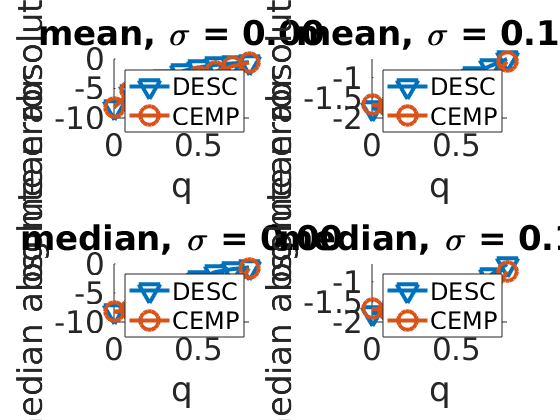


synthetic_svec_errors = csvread('synthetic_desc_vs_cemp_means_geodesic.csv');
clf;
tiledlayout(2,2);
for i = 1:2 % only plotting sigma 0 and 0.1
    %subplot(2,2,i);
    nexttile;
    hold on;
    xlim([0 0.8]);
    valrange = (1 + qvals*(i-1)):(qvals*i);
    data = synthetic_svec_errors(valrange, :);
    plot(q, log10(data(:,1)), '-v', 'DisplayName', 'DESC',...
        'LineWidth', 3, 'MarkerSize', markerSize);
    plot(q, log10(data(:,2)), '-o', 'DisplayName','CEMP',...
        'LineWidth', 3, 'MarkerSize', markerSize);
    xlabel('q');
    ylabel('log mean absolute error');
    legend('Location', 'northwest', 'FontSize', 18);
    noiseLevel = sprintf('mean, \\sigma = %0.2f', sigma(i));
    title(noiseLevel);
    ax = gca;
    ax.FontSize = 23;
    hold off;
end

synthetic_svec_errors = csvread('synthetic_desc_vs_cemp_medians_geodesic.csv');
for i = 1:2 % only sigma 0 and 0.1 are included
    %subplot(2,2,i+2);
    nexttile;
    hold on;
    xlim([0 0.8]);
    valrange = (1 + qvals*(i-1)):(qvals*i);
    data = synthetic_svec_errors(valrange, :);
    plot(q, log10(data(:,1)), '-v', 'DisplayName', 'DESC',...
        'LineWidth',3, 'MarkerSize', markerSize);
    plot(q, log10(data(:,2)), '-o', 'DisplayName','CEMP',...
        'LineWidth',3, 'MarkerSize', markerSize);
    xlabel('q');
    ylabel('log median absolute error');
    legend('Location', 'northwest','FontSize', 18);
    noiseLevel = sprintf('median, \\sigma = %0.2f', sigma(i));
    title(noiseLevel);
    ax = gca;
    ax.FontSize = 23;
    hold off;
end

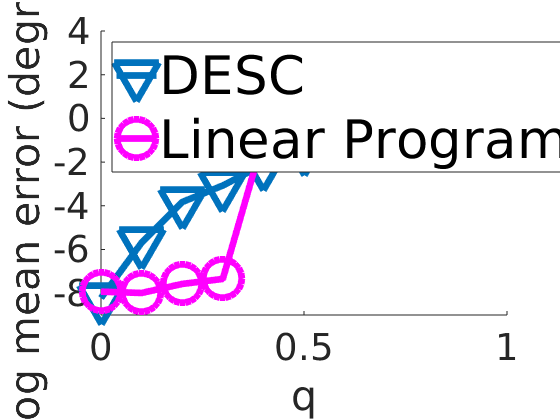

desc_vs_linprog_mean = csvread('synthetic_desc_vs_linprog_mean_rotation_error_geodesic.csv');
clf;
% tiledlayout(1,2);
% nexttile;
hold on;
plot(q, log10(desc_vs_linprog_mean(:,1)), '-v', 'DisplayName', 'DESC',...
    'LineWidth', 5, 'MarkerSize', markerSize+15);
plot(q, log10(desc_vs_linprog_mean(:,2)), '-o', 'DisplayName','Linear Programming',...
    'LineWidth', 5, 'MarkerSize', markerSize+15, 'Color', 'magenta');
xlabel('q');
ylabel('log mean error (degrees)');
ylim([-9 4]);
legend('Location', 'northwest', 'FontSize', 40);
% noiseLevel = sprintf('\\sigma = %0.2f', 0);
% title(noiseLevel);
ax = gca;
ax.FontSize = 28;
hold off;


% desc_vs_linprog_median = csvread('synthetic_desc_vs_linprog_median.csv');
% nexttile;
% hold on;
% plot(q, log10(desc_vs_linprog_median(:,1)), '-v', 'DisplayName', 'DESC',...
%     'LineWidth',3, 'MarkerSize', markerSize);
% plot(q, log10(desc_vs_linprog_median(:,2)), '-o', 'DisplayName','Linear Programming',...
%     'LineWidth',3, 'MarkerSize', markerSize, 'Color', 'magenta');
% xlabel('q');
% ylabel('log median absolute error');
% legend('Location', 'northwest','FontSize', 18);
% noiseLevel = sprintf('median, \\sigma = %0.2f', 0);
% title(noiseLevel);
% ax = gca;
% ax.FontSize = 20;
% hold off;


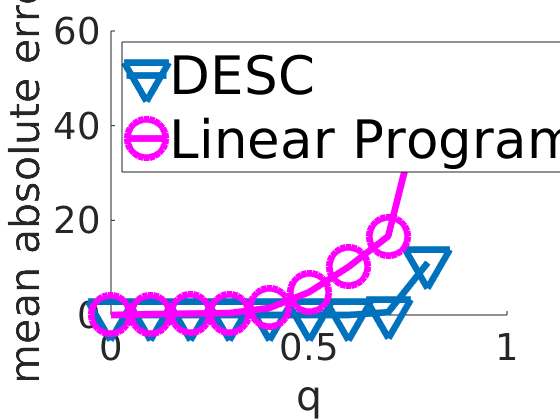

desc_vs_linprog_mean = csvread('synthetic_desc_vs_linprog_mean_svec_error_geodesic.csv');
clf;
% tiledlayout(1,2);
% nexttile;
hold on;
plot(q, desc_vs_linprog_mean(:,1), '-v', 'DisplayName', 'DESC',...
    'LineWidth', 5, 'MarkerSize', markerSize+15);
plot(q, desc_vs_linprog_mean(:,2), '-o', 'DisplayName','Linear Programming',...
    'LineWidth', 5, 'MarkerSize', markerSize+15, 'Color', 'magenta');
xlabel('q');
ylabel('mean absolute error');
%ylim([-6 4]);
legend('Location', 'northwest', 'FontSize', 40);
% noiseLevel = sprintf('\\sigma = %0.2f', 0);
% title(noiseLevel);
ax = gca;
ax.FontSize = 28;
hold off;